%import
clear
clc
path = 'C:\Users\thamr\OneDrive\Desktop\finalMatlab\dataset-3a.xlsx';
Q1a = readmatrix(path,'Sheet','Q1A');
QHS1 = readmatrix(path,'Sheet','QH_S1');
QHS3 = readmatrix(path,'Sheet','QH_S3');

%Q ที่สถานี S3 (M7) โดยใช้ค่า Q ที่สถานี S1 และ S2 ระหว่าง Day 1 และ Day 60 
qData1 = Q1a(1:60,3);
qData2 = Q1a(1:60,4);
qData1 = qData1(~isnan(qData1));
qData2 = qData2(~isnan(qData2));
qData3 = qData2+qData1;

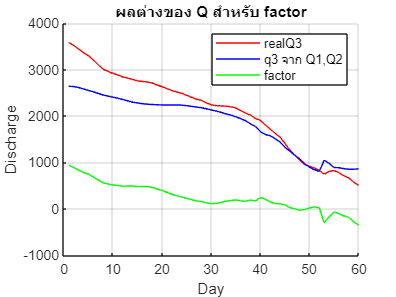

%factor ที่เกิดขึ้น เมื่อเปรียบเทียบกับข้อมูล Q จริง 
realData3 = Q1a(:,5);
realData3 = realData3(~isnan((realData3)));
factor = realData3 - qData3;
day = 1:length(factor);
hold on
plot(day,realData3,Color='r');
plot(day,qData3,Color='b');
plot(day,factor,Color='g');
xlabel("Day")
ylabel("Discharge")
title("ผลต่างของ Q สำหรับ factor")
legend("realQ3","q3 จาก Q1,Q2","factor")
grid on
hold off


xlswrite(path,factor,1,'F2');

sendQ = qData3;
sendQ = sendQ(~isnan(sendQ));
for i=1:length(sendQ)
    data = sendQ(i);
    url = 'http://192.168.1.143:5000/senddatah/';
    url = [url,num2str(data)];
    response = webread(url); 
    fprintf("SendQ3 Done %d %s\n",i,response)
end

Error using webread
The connection to URL 'http://192.168.1.143:5000/senddatah/2641.4' timed out after 5.000 seconds. The reason is "Failed to connect to 192.168.1.143 port 5000 after 5113 ms: Timeout was reached". Perhaps the server is not responding or weboptions.Timeout needs to be set to a higher value.